# visualizing 2d slices of B_sec(t) heatmaps with field lines 

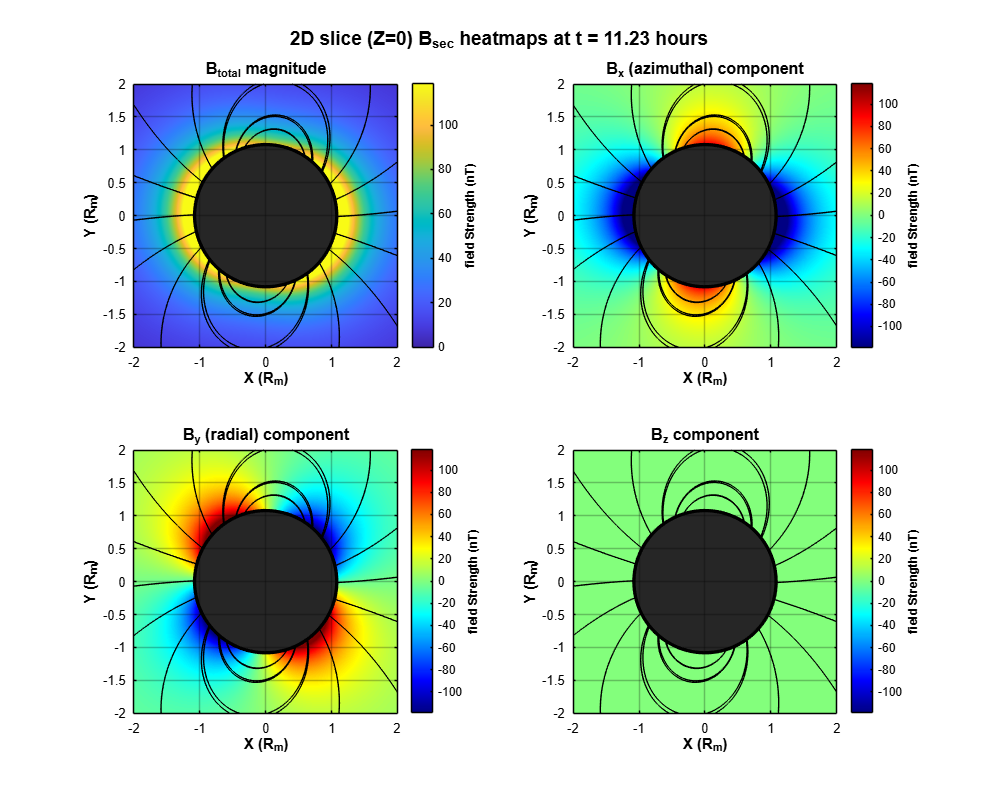

clear

% define constants

r_m = 1560; % Europa radius (km)

B_prim = 250; % approximate background field amplitude nT

A = 0.95; % amplitude response factor

phi = 0.14; % phase lag in radians (around 8 deg)

synodic_period = 11.23 * 3600; % 11.23 hr period

omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)


% inducing field direction

e0x = [1;0;0];

e0y = [0;1;0];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% create spatial grid

grid_limit = 2.5 * r_m;

num_points = 80;

[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
    linspace(-grid_limit, grid_limit, num_points), ...
    linspace(-grid_limit, grid_limit, num_points));


% find the index corresponding to the Z = 0 plane

[~, z_idx] = min(abs(Z(1,1,:)));


% extract the 2D plane grid coordinates

X_slice = X(:,:,z_idx);
Y_slice = Y(:,:,z_idx);


% fixed seed points
% ring of seeds around the moon, outside r_m so lines don't start
% inside the NaN-masked interior

seed_radius = 1.3 * r_m;
num_seeds = 24;
seed_angles = linspace(0, 2*pi, num_seeds + 1);
seed_angles(end) = []; % avoid duplicate point at 0 == 2pi

seedX = seed_radius * cos(seed_angles(:));
seedY = seed_radius * sin(seed_angles(:));


% set up animation time array

num_frames = 100;

time_steps = linspace(0, synodic_period, num_frames);


% create figure once outside the loop with a white background

fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 1000, 800]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% animation loop

for t = time_steps

    % initialize arrays to hold 2D field slice components
    Bx_slice = NaN(size(X_slice));
    By_slice = NaN(size(X_slice));
    Bz_slice = NaN(size(X_slice));

    % loop through the 2D grid slice to compute spatial part of equations
    for i = 1:numel(X_slice)

        r_vec = [X_slice(i); Y_slice(i); 0];
        r = norm(r_vec);

        if r < r_m
            continue;
        end

        % X EQUATION
        r_dot_e0x = dot(r_vec, e0x);
        spatial_bracketx = 3 * r_dot_e0x * r_vec - (r^2) * e0x;
        coefx = - (A * B_prim * r_m^3) * (cos(omega * t - phi)) / (2 * r^5);

        % Y EQUATION
        r_dot_e0y = dot(r_vec, e0y);
        spatial_brackety = 3 * r_dot_e0y * r_vec - (r^2) * e0y;
        coefy = - (A * B_prim * r_m^3) * (sin(omega * t - phi)) / (2 * r^5);

        B_vector = (coefx * spatial_bracketx) + (coefy * spatial_brackety);
        Bx_slice(i) = B_vector(1);
        By_slice(i) = B_vector(2);
        Bz_slice(i) = B_vector(3);
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    Btot_slice = sqrt(Bx_slice.^2 + By_slice.^2 + Bz_slice.^2);

    % streamlines
    % same technique as the 3D stream3 version
    verts_forward  = stream2(X_slice, Y_slice, Bx_slice, By_slice, seedX, seedY);
    verts_backward = stream2(X_slice, Y_slice, -Bx_slice, -By_slice, seedX, seedY);

    stitched_lines = cell(num_seeds, 1);
    for k = 1:num_seeds
        v_f = verts_forward{k};
        v_b = verts_backward{k};

        if isempty(v_f) && isempty(v_b)
            stitched_lines{k} = [];
        elseif isempty(v_f)
            stitched_lines{k} = v_b;
        elseif isempty(v_b)
            stitched_lines{k} = v_f;
        else
            stitched_lines{k} = [flipud(v_b); v_f];
        end
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    clf;

    titles = {'B_{total} magnitude', 'B_x (azimuthal) component', 'B_y (radial) component', 'B_z component'};
    data_slices = {Btot_slice, Bx_slice, By_slice, Bz_slice};

    max_val = A * B_prim / 2;

    for p = 1:4
        ax = subplot(2, 2, p);

        h = pcolor(X_slice / r_m, Y_slice / r_m, data_slices{p});
        set(h, 'EdgeColor', 'none');
        shading interp;
        axis equal;

        xlim([-2, 2]); ylim([-2, 2]);

        hold on;

        % draw lines
        for k = 1:num_seeds
            v = stitched_lines{k};
            if isempty(v)
                continue;
            end
            plot(v(:,1) / r_m, v(:,2) / r_m, 'k-', 'LineWidth', 0.75);
        end
      %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        set(ax, 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', 'Layer', 'top');
        grid on;

        xlabel('X (R_m)', 'Color', 'k', 'FontSize', 11, 'FontWeight', 'bold');
        ylabel('Y (R_m)', 'Color', 'k', 'FontSize', 11, 'FontWeight', 'bold');
        title(titles{p}, 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');

        c = colorbar;
        ylabel(c, 'field Strength (nT)', 'Color', 'k', 'FontWeight', 'bold');
        set(c, 'Color', 'k');

        if p == 1
            clim([0, max_val]);
            colormap(gca, 'parula');
        else
            clim([-max_val, max_val]);
            colormap(gca, 'jet');
        end

        theta_circle = linspace(0, 2*pi, 100);
        fill(1.08*cos(theta_circle), 1.08*sin(theta_circle), [0.15 0.15 0.15], ...
             'EdgeColor', 'k', 'LineWidth', 2.5);
    end

    sgtitle(sprintf('2D slice (Z=0) B_s_e_c heatmaps at t = %.2f hours', t/3600), ...
        'Color', 'k', 'FontSize', 14, 'FontWeight', 'bold');

    drawnow;
    pause(0.3);

end